矩阵建立、查找、取值、删除、取子式、对角矩阵、上下三角矩阵、求 逆、特征值特征向量

A=[1 2 3 ; 4 5 6 ; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


A(2,2)==A(5)

ans = logical
   1


%将第二行删除
A(2,:)=[];
disp(A)

     1     2     3
     7     8     9



A=[1 2 3 ; 4 5 6 ; 7 8 9];
A_1=A(1:2,2:3)

A_1 =      2     3
     5     6


%求逆矩阵
syms a b c d  e f g h k;
B=[a b c;d e f ; g h k];
B_1=B^-1

$$B\_1 = \begin{array}{l} \left(\begin{array}{ccc} \frac{f\,h-e\,k}{\sigma_{1}} & -\frac{c\,h-b\,k}{\sigma_{1}} & -\frac{b\,f-c\,e}{\sigma_{1}}\\ -\frac{f\,g-d\,k}{\sigma_{1}} & \frac{c\,g-a\,k}{\sigma_{1}} & \frac{a\,f-c\,d}{\sigma_{1}}\\ -\frac{d\,h-e\,g}{\sigma_{1}} & \frac{a\,h-b\,g}{\sigma_{1}} & -\frac{a\,e-b\,d}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a\,f\,h-b\,f\,g-c\,d\,h+c\,e\,g-a\,e\,k+b\,d\,k \end{array}$$

%求特征值，特征向量
[e,V]=eig(B)    % e:特征值，V：特征向量

$$V = \begin{array}{l} \left(\begin{array}{ccc} \frac{a}{3}+\frac{e}{3}+\frac{k}{3}+\sigma_{2}+\frac{\sigma_{3}}{\sigma_{2}} & 0 & 0\\ 0 & \frac{a}{3}+\frac{e}{3}+\frac{k}{3}-\frac{\sigma_{2}}{2}-\frac{\sigma_{3}}{2\,\sigma_{2}}-\sigma_{1} & 0\\ 0 & 0 & \frac{a}{3}+\frac{e}{3}+\frac{k}{3}-\frac{\sigma_{2}}{2}-\frac{\sigma_{3}}{2\,\sigma_{2}}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\sigma_{2}-\frac{\sigma_{3}}{\sigma_{2}}\right)\,\mathrm{i}}{2}\\ \sigma_{2}={\left(\sqrt{{\left(\sigma_{4}-\sigma_{5}+\sigma_{11}-\sigma_{10}-\sigma_{9}+\sigma_{8}-\sigma_{7}+\sigma_{6}\right)}^{2}-{\sigma_{3}}^{3}}-\sigma_{4}+\sigma_{5}-\sigma_{11}+\sigma_{10}+\sigma_{9}-\sigma_{8}+\sigma_{7}-\sigma_{6}\right)}^{1/3}\\ \sigma_{3}=\frac{b\,d}{3}-\frac{a\,e}{3}+\frac{c\,g}{3}-\frac{a\,k}{3}+\frac{f\,h}{3}-\frac{e\,k}{3}+\frac{{\left(a+e+k\right)}^{2}}{9}\\ \sigma_{4}=\frac{\left(a+e+k\right)\,\left(a\,e-b\,d-c\,g+a\,k-f\,h+e\,k\right)}{6}\\ \sigma_{5}=\frac{{\left(a+e+k\right)}^{3}}{27}\\ \sigma_{6}=\frac{b\,d\,k}{2}\\ \sigma_{7}=\frac{a\,e\,k}{2}\\ \sigma_{8}=\frac{c\,e\,g}{2}\\ \sigma_{9}=\frac{c\,d\,h}{2}\\ \sigma_{10}=\frac{b\,f\,g}{2}\\ \sigma_{11}=\frac{a\,f\,h}{2} \end{array}$$

掌握if、switch 选择语句的基本用法 

score=70;
if score >= 90
    G='A';
    fprintf('Excelent!');
else
    G='B';
    fprintf('Not Very Bad.');
end

Not Very Bad.

switch G
    case 'A'
        fprintf('Excelent');
    case 'B'
        fprintf('Not Very Bad.');
end

Not Very Bad.

掌握for、while 循环语句的基本用法

%以求阶乘为例
n=1;
sum=1;
if n == 0
    sum=1;
else
    for c = 1:1:n
        sum=sum*c;
    end
end
disp(sum);

     1



使用plot、fplot，fimplicit 绘制二维图，会使用surf、mesh，fsurf，fimplicit3 等绘制曲面图，并能设置图像的标题、图例以及坐标轴的标记等操作。

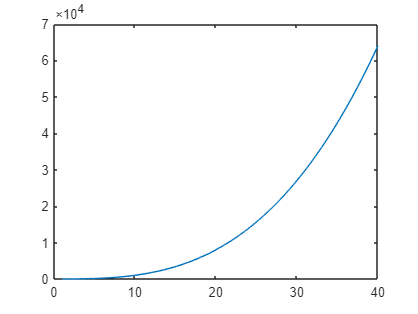

x=1:0.02:40;
y=x.^3+2*x;
plot(x,y)

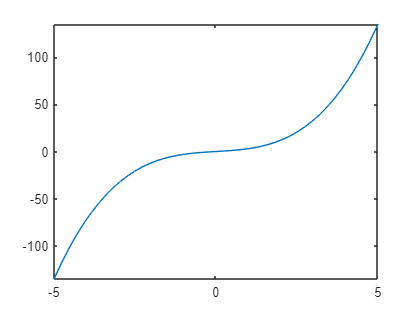

f=@(x)x.^3+2*x;
fplot(f)

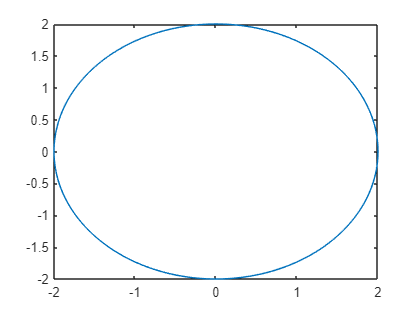

f=@(x,y)x.^2+y.^2-4;
fimplicit(f)

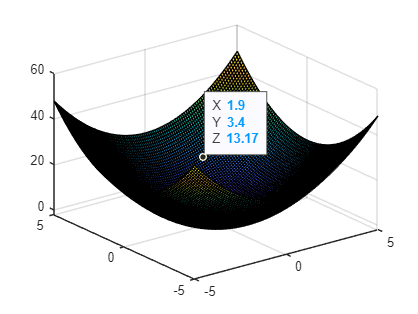

x=-5:0.1:5;
y=-5:0.1:5;
[X,Y]=meshgrid(x,y);
Z=X.^2+Y.^2-2;
surf(X,Y,Z)

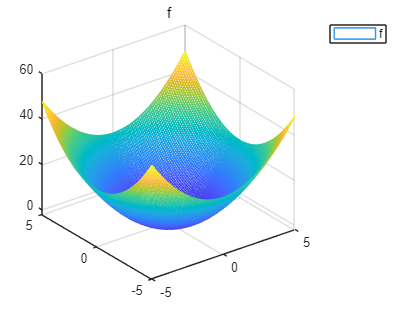

x=-5:0.1:5;
y=-5:0.1:5;
[X,Y]=meshgrid(x,y);
Z=X.^2+Y.^2-2;
mesh(X,Y,Z)
title('f')
legend('f')

使用sum、max、min、sort、std、cov、corrcoef、eig，det 

clear;clc;
A=[1 2 3;4 5 6;7 8 9];
sum(A)

ans =     12    15    18


max(A)

ans =      7     8     9


B=[2 4 6 ;7 9 3; 6 8 1];
sort(B)

ans =      2     4     1
     6     8     3
     7     9     6


std(A)

ans =      3     3     3


计算一个正态分布的随机矩阵的相关系数和 p 值，其中添加的第四列等于其他三列之和。由于 `A` 的最后一列是其他列的线性组合，第四个变量与其他三个变量中的每一个之间建立了相关性。因此，`P` 的第四行和第四列包含非常小的 p 值，将其标识为显著相关。

A = randn(50,3);       
A(:,4) = sum(A,2); 
[R,P] = corrcoef(A)

R =     1.0000    0.1135    0.0879    0.7314
    0.1135    1.0000   -0.1451    0.5082
    0.0879   -0.1451    1.0000    0.5199
    0.7314    0.5082    0.5199    1.0000


P =     1.0000    0.4325    0.5438    0.0000
    0.4325    1.0000    0.3146    0.0002
    0.5438    0.3146    1.0000    0.0001
    0.0000    0.0002    0.0001    1.0000


f=[3 -5 -7 5 6];
g=[0 0 3 5 -3];
f+g

ans =      3    -5    -4    10     3


%乘法用conv计算
conv(f,g)

ans =      0     0     9     0   -55    -5    64    15   -18


h=[2,1,3];
[Q,r]=deconv(f,h) %Q是商，r是余数

Q =     1.5000   -3.2500   -4.1250


r =          0         0         0   18.8750   18.3750


roots(h)    % 求根

ans =   -0.2500 + 1.1990i
  -0.2500 - 1.1990i


% 矩阵多项式
A=[2 0 0;1 1 1;1 -1 3];
f=[1 -2 0 1 -1];
y=polyvalm(f,A)

y =      1     0     0
     9    -8     9
     9    -9    10


用integral、integral2、integral3 求积分积分的数值解，求重积分时，当上 下限是函数时，需懂得上下限函数的表示方法

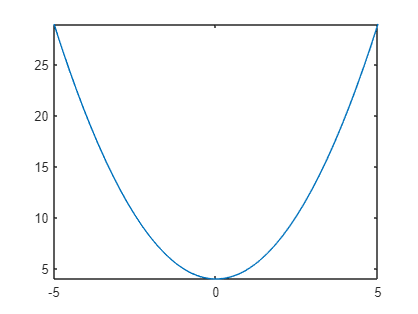

clear;clc;
f=@(x)x.^2+4;
fplot(f)

q=integral(f,0,1)

q = 4.3333

%二重积分
fun = @(x,y) 1./( sqrt(x + y) .* (1 + x + y).^2 );
q=integral2(fun,0,1,0,1)

q = 0.3695

用rref化简矩阵

A=magic(3);
q=rref(A)

q =      1     0     0
     0     1     0
     0     0     1
